n = 1000;                                                                   
a(:,1) = normrnd(0,1,[n,1]);                                               
a(:,2) = normrnd(0,1,[n,1]);                                                
b(:,1) = normrnd(0,1,[n,1]);                                               
b(:,2) = b(:,1)*0.5+0.5*normrnd(0,1,[n,1]); 

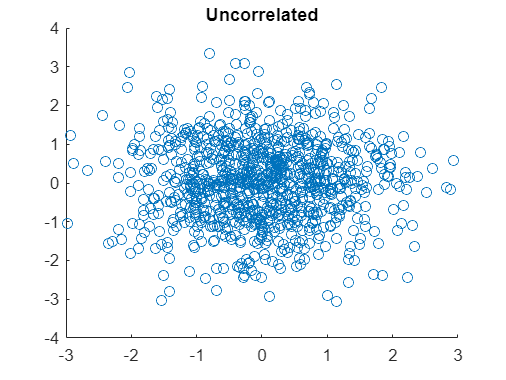

  scatter(a(:,1), a(:,2))
  title("Uncorrelated")

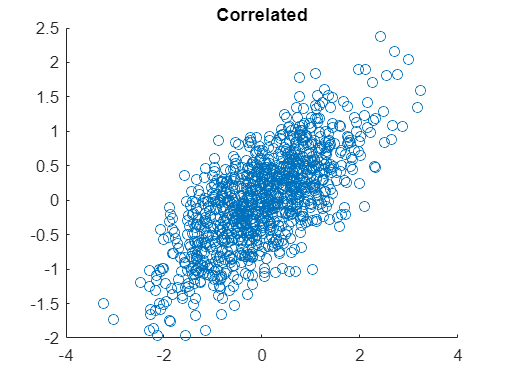

  scatter(b(:,1), b(:,2))
  title("Correlated")

  cov_a = cov(a)

cov_a =     0.9635   -0.0121
   -0.0121    1.0625


  cov_b = cov(b)

cov_b =     1.0112    0.4882
    0.4882    0.4712


  [coeff, score, latent] = pca (b)

coeff =     0.8614   -0.5079
    0.5079    0.8614


score =     1.2922    0.1895
   -1.3769   -0.3067
    0.0758   -0.0046
   -0.7883   -0.4597
   -2.5808   -0.3030
   -0.1921    0.7437
   -0.8349    0.1643
    1.5139   -0.4179
   -0.6062    0.3660
   -0.5864    0.9129


latent =     1.2991
    0.1833


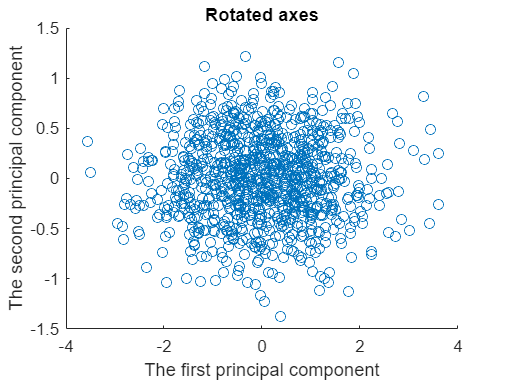

  scatter(score(:,1), score(:,2))
  title("Rotated axes")
  xlabel("The first principal component")
  ylabel("The second principal component")


  disp(["The fraction of variation captured by first principal component = ", latent(1)/(latent(1)+latent(2))])

    "The fraction of variation captured by first principal component = "    "0.87638"



  disp(["The fraction of variation captured by second principal component =", latent(2)/(latent(1)+latent(2))])

    "The fraction of variation captured by second principal component ="    "0.12362"

